# HW9

syms a y theta

2/(pi*a)*int((a*sin(theta))^5*sin(theta),0,pi)

$$ans = \frac{5\,a^{4}}{8}$$

syms a omega t

2/(pi*a)*int(a^3*omega^3*cos(omega*t)^3*sin(omega*t)*omega, 0, pi/omega)

$$ans = 0$$

y0 = [1;0]

y0 =      1
     0


mu = 2.1

mu = 2.1000

tf = 60

tf = 60

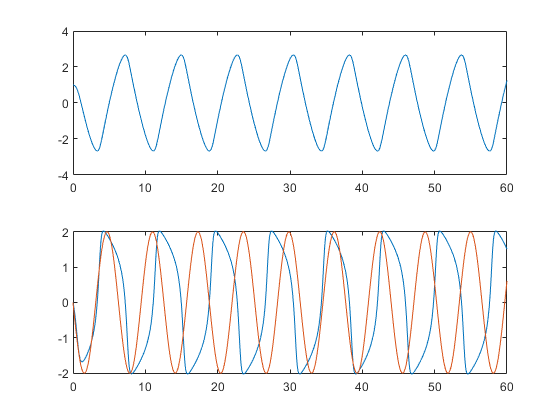


f = @(t,y) [y(2); -y(1)-mu*(y(2)^3/3-y(2))];

[t,y] = ode45(f, [0, tf], y0);

figure
subplot(2,1,1)
plot(t, y(:,1))

subplot(2,1,2)
plot(t, y(:,2))
hold on

a = 2;
omega = -1;
plot(t, a*sin(omega*t))

syms a h t omega na

2/(pi*a)

$$ans = \frac{2}{a\,\pi }$$


int(-sin(omega*t)*omega, t, -h, 0)

$$ans = 1-\cos\left(h\,\omega \right)$$

int(sin(omega*t)*omega, t, 0, pi/omega-h)

$$ans = \cos\left(h\,\omega \right)+1$$

$$f1 = \omega -2\,\mathrm{na}\,\sin\left(h\,\omega \right)=0$$

$$f2 = 2\,\mathrm{na}\,\cos\left(h\,\omega \right)+1=0$$

ans = struct with fields:
    omega: [0×1 sym]
       na: [0×1 sym]


figure
plot(x.Time, x.Data)
hold on
omega = 0.2862;
T = 2*pi/omega

T = 21.9538

h = 10;
N = -1/(2*cos(omega*h))

N = 0.5202

omega/(2*sin(omega*h))

ans = 0.5185

a = 4/(pi*N)

a = 2.4476

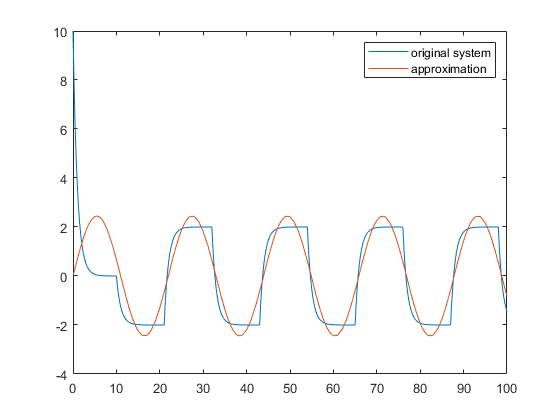

plot(x.Time, a*sin(omega*x.Time))
legend('original system','approximation')

sys = tf([1],[1,0,0])


sys =
 
   1
  ---
  s^2
 
Continuous-time transfer function.




ki = 0.15

ki = 0.1500

c = pid(1,ki,2)


c =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1, Ki = 0.15, Kd = 2
 
Continuous-time PID controller in parallel form.



T = feedback(c*sys,1)


T =
 
     2 s^2 + s + 0.15
  ----------------------
  s^3 + 2 s^2 + s + 0.15
 
Continuous-time transfer function.



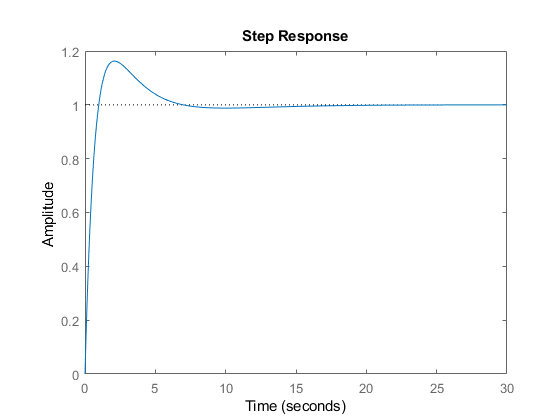

step(T)

syms e theta ki a
2/(pi*a)*int(ki*a*cos(theta)*sin(theta),theta,0, pi-e)

$$ans = \frac{\mathrm{ki}\,{\sin\left(e\right)}^{2}}{\pi }$$